# Assignment 03 - A.A. 2023/24

close all
clear
clc

## 0) Data

Loading data and plotting time histories

% Loading data
load('Data')
t=Data(:,1);
F=Data(:,2);
x=Data(:,3:end);    % displacements in the 4 columns
np=size(x,1);        % number of samples
nj=size(x,2);        % number of displacements

dt=t(2)-t(1);        % acquisition period
fsamp=1/dt;            % sampling frequency
disp(' ')

disp(['Number of sensors: ' num2str(nj)])

Number of sensors: 4


disp(['dt [s]: ' num2str(dt)])

dt [s]: 0.001


disp(['np [-]: ' num2str(np)])

np [-]: 60001


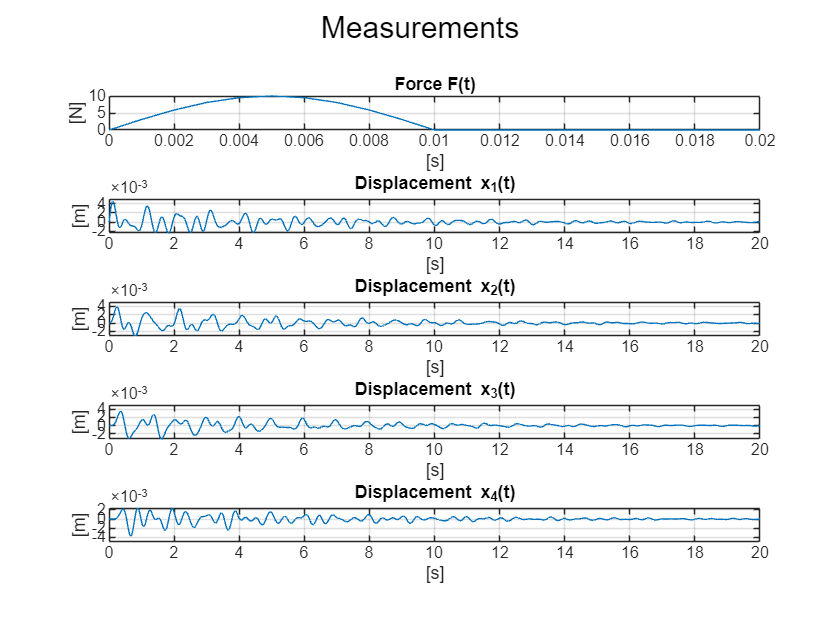


% Plots
figure()
sgtitle("Measurements");

subplot(5, 1, 1);
plot(t, F)
grid on;
title("Force F(t)");
ylabel("[N]");
xlabel("[s]");
xlim([0, 0.02]);

subplot(5, 1, 2);
plot(t, x(:, 1))
grid on;
title("Displacement x_1(t)");
ylabel("[m]");
xlabel("[s]");
xlim([0, 20]);

subplot(5, 1, 3);
plot(t, x(:, 2))
grid on;
title("Displacement x_2(t)");
ylabel("[m]");
xlabel("[s]");
xlim([0, 20]);

subplot(5, 1, 4);
plot(t, x(:, 3))
grid on;
title("Displacement x_3(t)");
ylabel("[m]");
xlabel("[s]");
xlim([0, 20]);

subplot(5, 1, 5);
plot(t, x(:, 4))
grid on;
title("Displacement x_4(t)");
ylabel("[m]");
xlabel("[s]");
xlim([0, 20]);

## 1) Experimental FRF

Plot the "experimental" FRF diagrams.

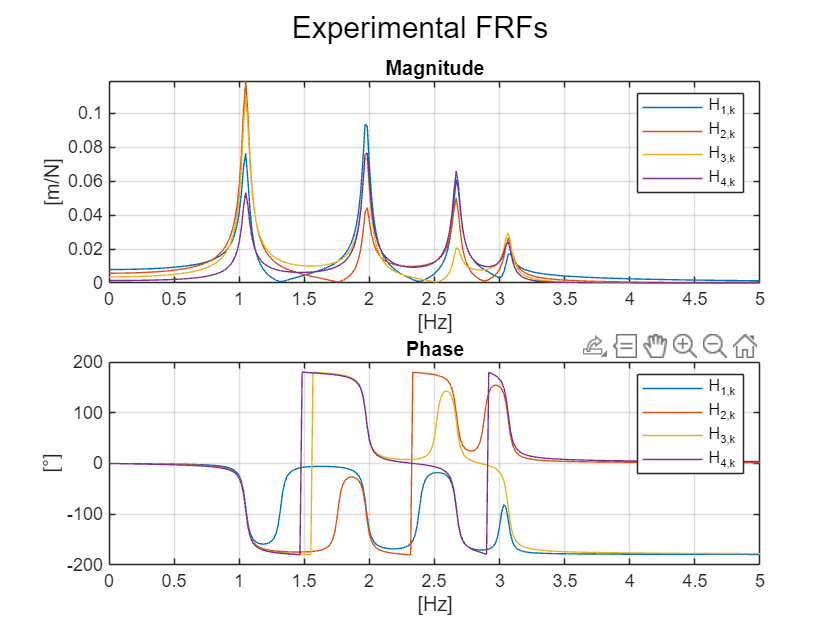

% Force and displacements spectra
[x_fft, frq] = ffg(x, np, dt);
[F_fft, frq] = ffg(F, np, dt);

% Experimental FRFs = ratio output/input
Hjk_exp = x_fft./F_fft;

% Plots
figure()
sgtitle("Experimental FRFs")

subplot(2, 1, 1);
for i=1:nj
    plot(frq, abs(Hjk_exp(:, i)))
    hold on;
end
grid on;
title("Magnitude");
ylabel("[m/N]");
xlabel("[Hz]");
xlim([0, 5]);
legend("H_{1,k}", "H_{2,k}", "H_{3,k}", "H_{4,k}");

subplot(2, 1, 2);
for i=1:nj
    plot(frq, angle(Hjk_exp(:, i))*180/pi)
    hold on
end
grid on;
title("Phase");
ylabel("[°]");
xlabel("[Hz]");
xlim([0, 5]);
legend("H_{1,k}", "H_{2,k}", "H_{3,k}", "H_{4,k}");

## 2) Parameters estimation - simplified method

Estimate the natural frequencies, damping ratios and mode shapes of the resonating modes in the range $0-5\;\textrm{Hz}$ employing simplified methods (e.g. half power point method). Comment the obtained results.

Frequency range


- fmin [Hz]: 0.79999


- fmax [Hz]: 1.2


Number of points for the identification: 25


Initial guess f_0 [Hz]: 1.05


Initial guess h [-]:    0.028582


Initial guess A_0 [Hz]: 0.18914


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000001 



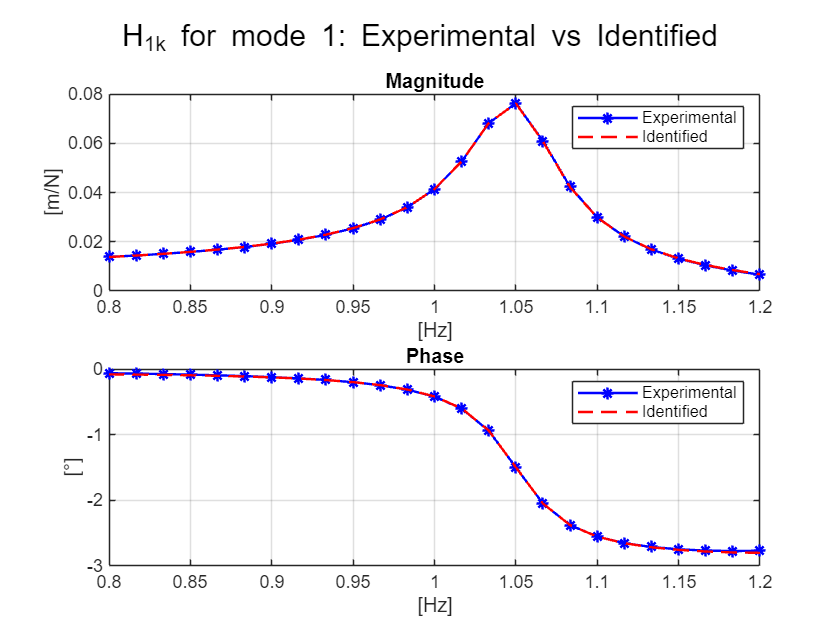

Frequency range


- fmin [Hz]: 1.7


- fmax [Hz]: 2.2


Number of points for the identification: 31


Initial guess f_0 [Hz]: 1.9666


Initial guess h [-]:    0.016098


Initial guess A_0 [Hz]: 0.43347


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000009 



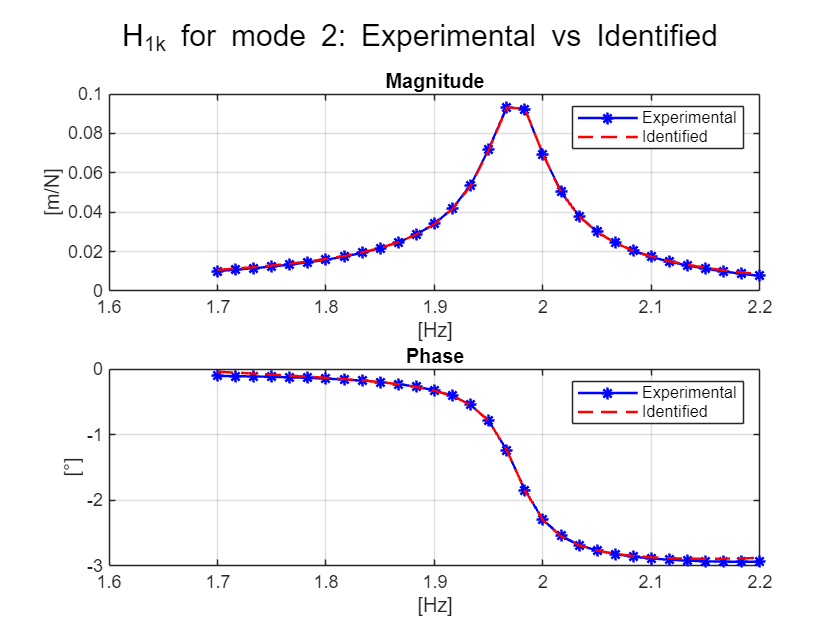

Frequency range


- fmin [Hz]: 2.5


- fmax [Hz]: 2.8


Number of points for the identification: 19


Initial guess f_0 [Hz]: 2.6666


Initial guess h [-]:    0.011303


Initial guess A_0 [Hz]: 0.38518


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000004 



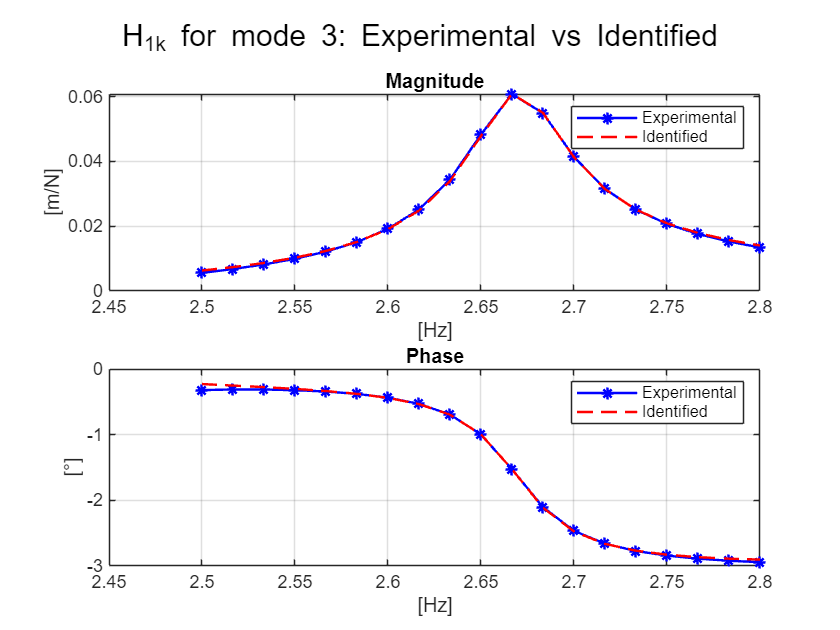

Frequency range


- fmin [Hz]: 3


- fmax [Hz]: 3.1999


Number of points for the identification: 13


Initial guess f_0 [Hz]: 3.0833


Initial guess h [-]:    0.014387


Initial guess A_0 [Hz]: 0.12091


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000002 



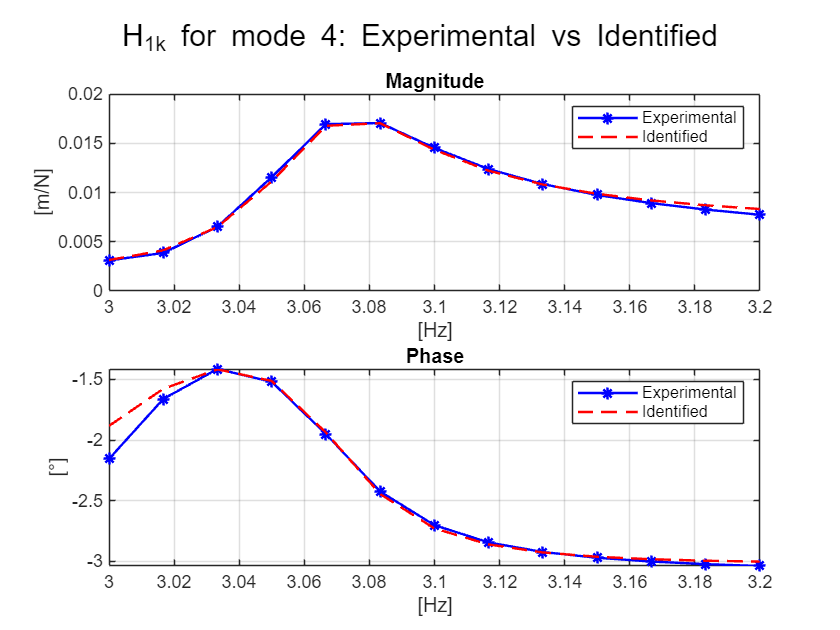

Frequency range


- fmin [Hz]: 0.79999


- fmax [Hz]: 1.2


Number of points for the identification: 25


Initial guess f_0 [Hz]: 1.05


Initial guess h [-]:    0.028302


Initial guess A_0 [Hz]: 0.29276


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000000 



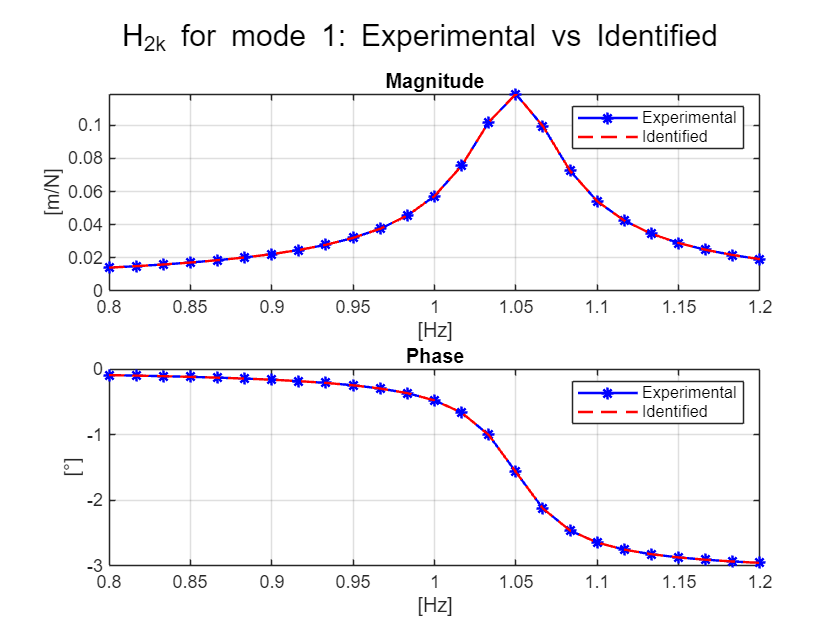

Frequency range


- fmin [Hz]: 1.7


- fmax [Hz]: 2.2


Number of points for the identification: 31


Initial guess f_0 [Hz]: 1.9833


Initial guess h [-]:    0.016028


Initial guess A_0 [Hz]: 0.20312


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000001 



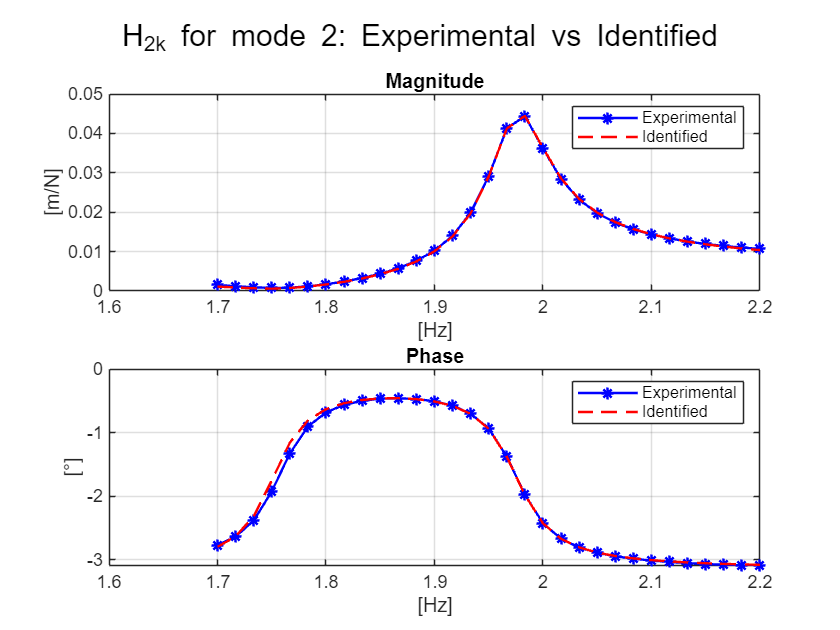

Frequency range


- fmin [Hz]: 2.5


- fmax [Hz]: 2.8


Number of points for the identification: 19


Initial guess f_0 [Hz]: 2.6666


Initial guess h [-]:    0.011311


Initial guess A_0 [Hz]: -0.31213


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000000 



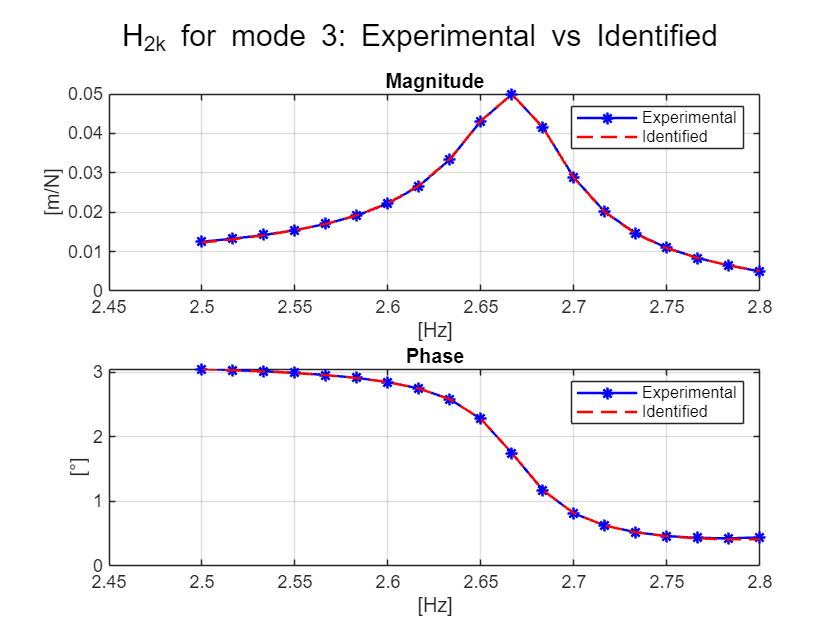

Frequency range


- fmin [Hz]: 3


- fmax [Hz]: 3.1999


Number of points for the identification: 13


Initial guess f_0 [Hz]: 3.0666


Initial guess h [-]:    0.0098626


Initial guess A_0 [Hz]: -0.1943


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000001 



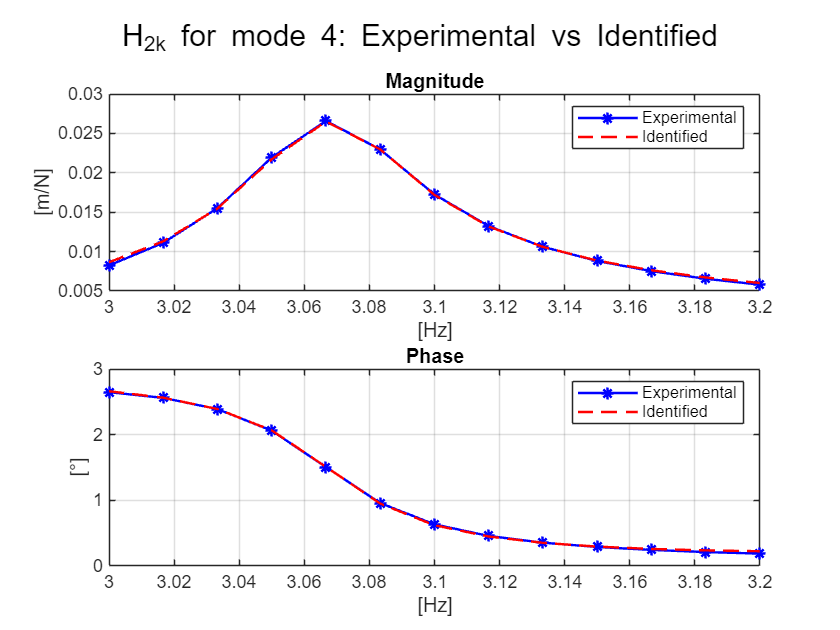

Frequency range


- fmin [Hz]: 0.79999


- fmax [Hz]: 1.2


Number of points for the identification: 25


Initial guess f_0 [Hz]: 1.05


Initial guess h [-]:    0.028259


Initial guess A_0 [Hz]: 0.27038


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000000 



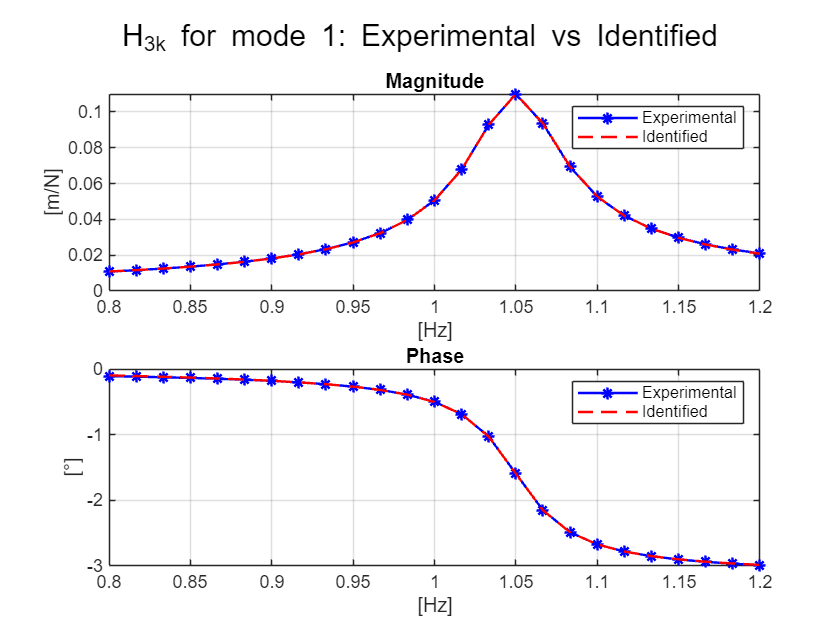

Frequency range


- fmin [Hz]: 1.7


- fmax [Hz]: 2.2


Number of points for the identification: 31


Initial guess f_0 [Hz]: 1.9666


Initial guess h [-]:    0.016018


Initial guess A_0 [Hz]: -0.33931


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000002 



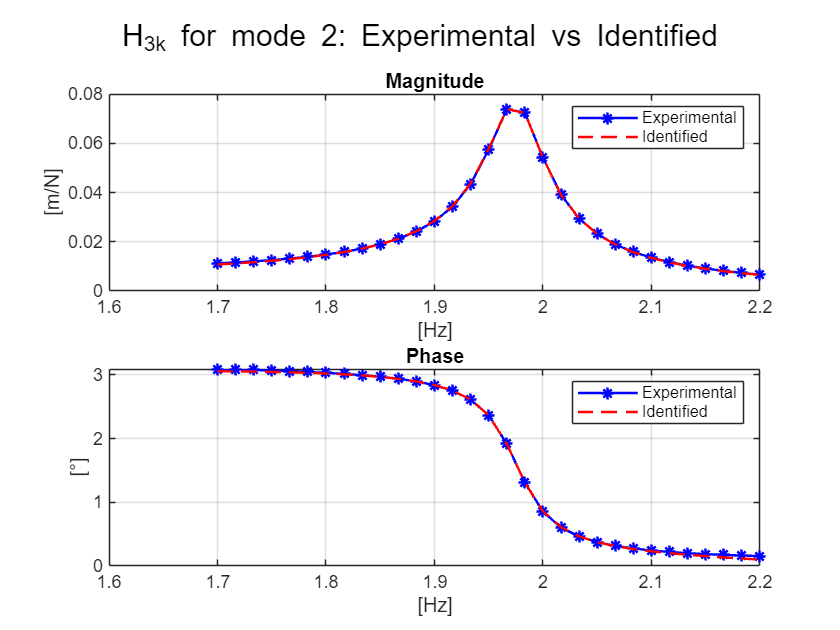

Frequency range


- fmin [Hz]: 2.5


- fmax [Hz]: 2.8


Number of points for the identification: 19


Initial guess f_0 [Hz]: 2.6666


Initial guess h [-]:    0.011504


Initial guess A_0 [Hz]: -0.13254


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000000 



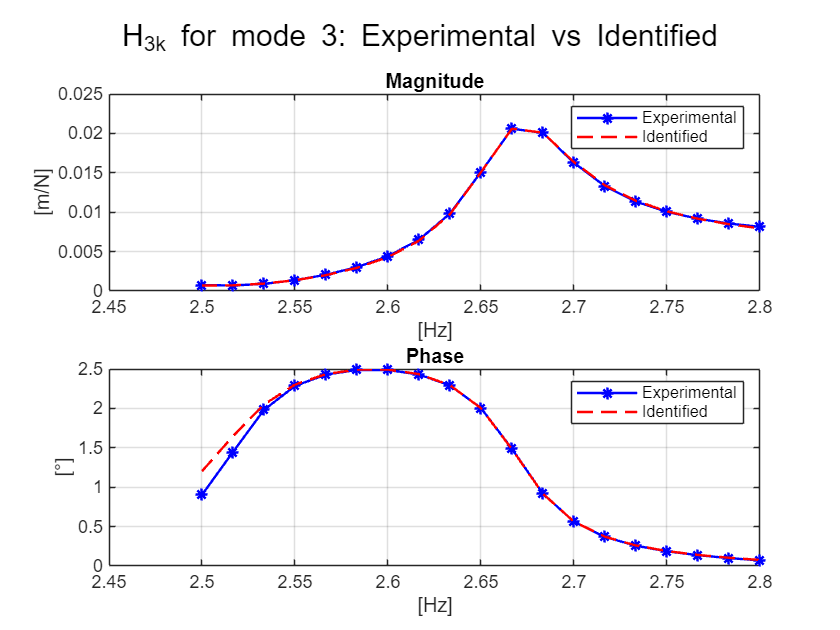

Frequency range


- fmin [Hz]: 3


- fmax [Hz]: 3.1999


Number of points for the identification: 13


Initial guess f_0 [Hz]: 3.0666


Initial guess h [-]:    0.0096574


Initial guess A_0 [Hz]: 0.21227


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000000 



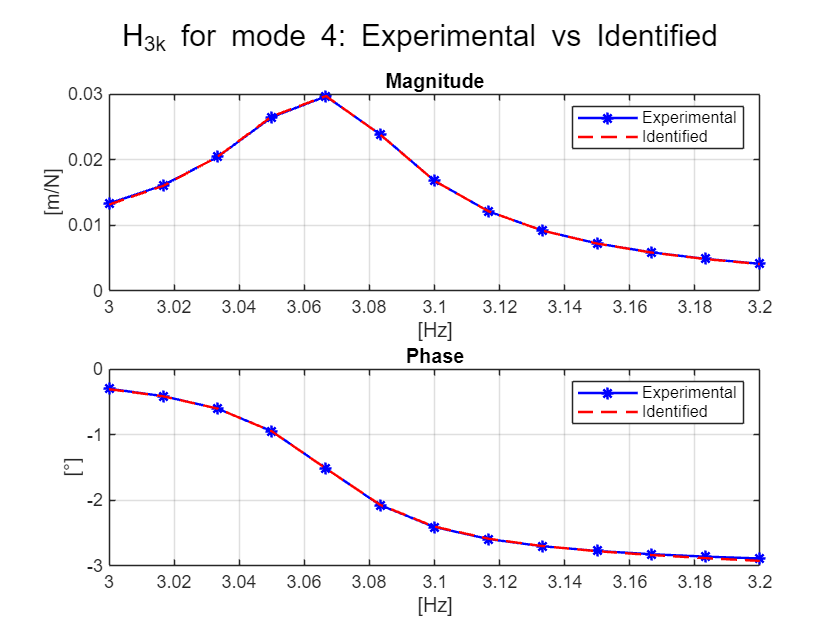

Frequency range


- fmin [Hz]: 0.79999


- fmax [Hz]: 1.2


Number of points for the identification: 25


Initial guess f_0 [Hz]: 1.05


Initial guess h [-]:    0.028247


Initial guess A_0 [Hz]: 0.13085


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000000 



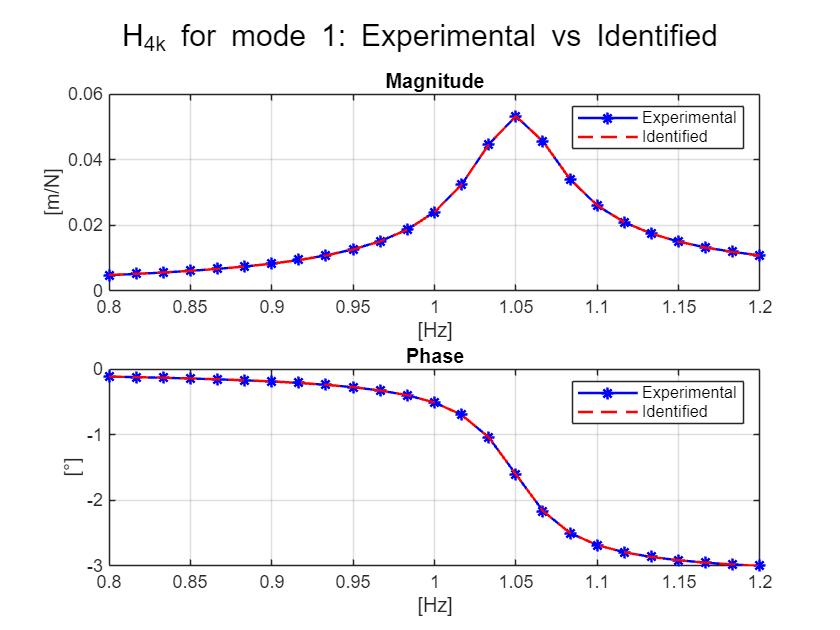

Frequency range


- fmin [Hz]: 1.7


- fmax [Hz]: 2.2


Number of points for the identification: 31


Initial guess f_0 [Hz]: 1.9833


Initial guess h [-]:    0.015753


Initial guess A_0 [Hz]: -0.35651


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000008 



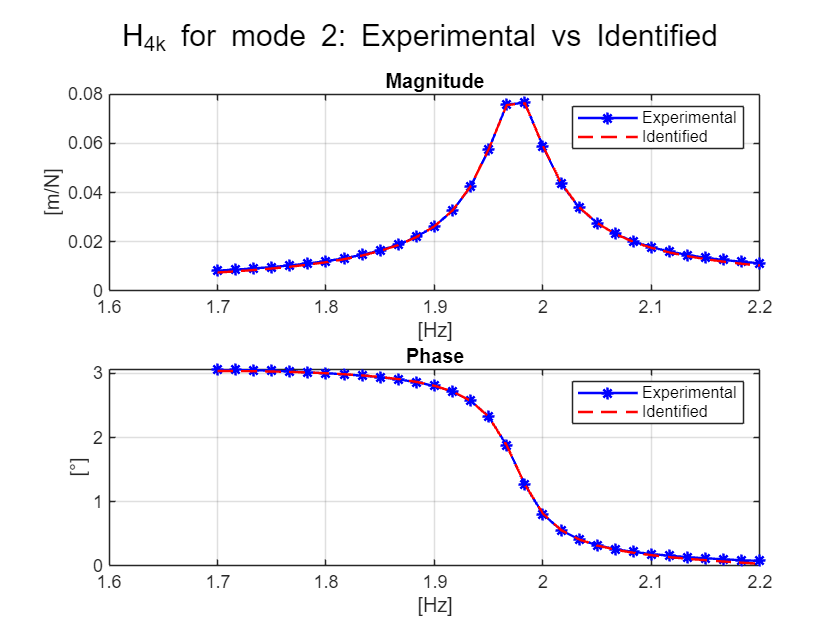

Frequency range


- fmin [Hz]: 2.5


- fmax [Hz]: 2.8


Number of points for the identification: 19


Initial guess f_0 [Hz]: 2.6666


Initial guess h [-]:    0.011111


Initial guess A_0 [Hz]: 0.40935


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000004 



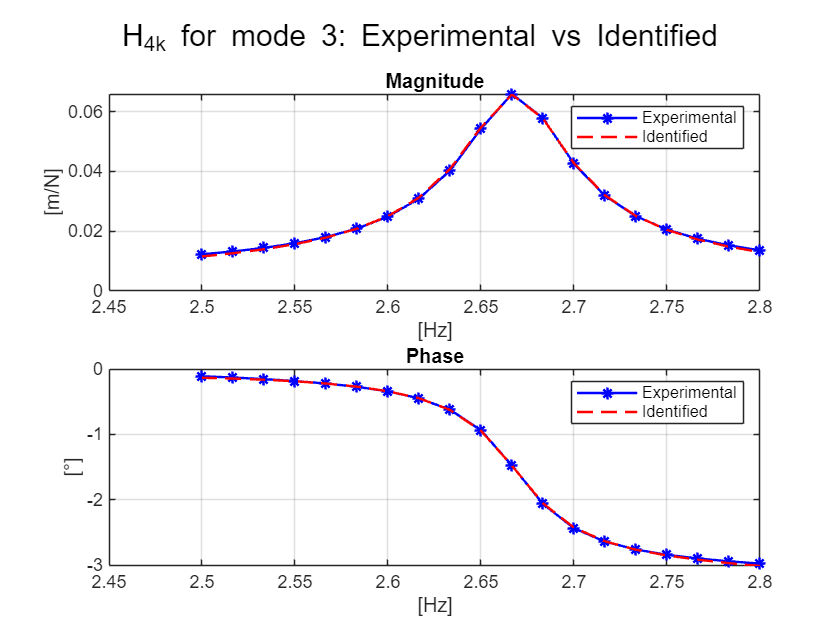

Frequency range


- fmin [Hz]: 3


- fmax [Hz]: 3.1999


Number of points for the identification: 13


Initial guess f_0 [Hz]: 3.0666


Initial guess h [-]:    0.0096322


Initial guess A_0 [Hz]: -0.17359


 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.000001 



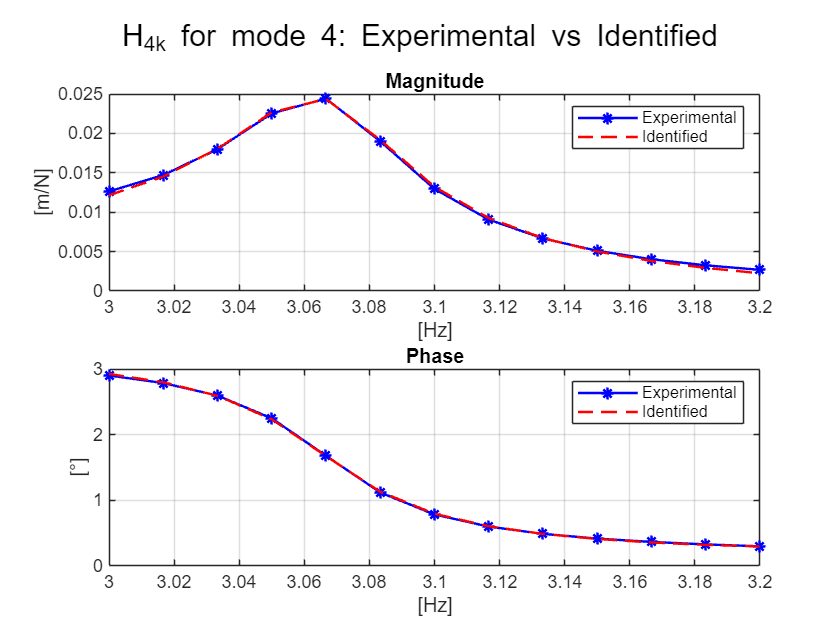

fini = [0.8, 1.7, 2.5, 3];        % Lower f in band
ffin = [1.2, 2.2, 2.8, 3.2];        % Higher f in band

for jj = 1:4        % for each FRF
    for i = 1:4        % for each mode
        % Indexes indentification
        iini = min(find(round(frq*1000)/1000 >= fini(i)));
        ifin = max(find(round(frq*1000)/1000 <= ffin(i)));
        disp('Frequency range')
        disp(['- fmin [Hz]: ' num2str(frq(iini))])
        disp(['- fmax [Hz]: ' num2str(frq(ifin))]) 
        
        % Count of points for identification
        npid = ifin - iini + 1;
        disp(['Number of points for the identification: ' num2str(npid)])
        
        % FRF evaluated in [fini, ffin]
        rfHjki = frq(iini:ifin);
        Hjkiexp = Hjk_exp(iini:ifin,:);
        
        % First guess of parameters: SIMPLIFIED METHODS
        
        % Natural frequency
        [vmax, iwmax] = max(abs(Hjkiexp(:, jj)));        % Maximum of |FRF| inside [fini, ffin]
        f0i = rfHjki(iwmax);        % Frequency [Hz] of the maximum
        w0i0 = 2*pi*f0i;            % Resonance frequency [rad/s]
        
        % Adimensional damping ration (phase derivative)
        derFIjki = (angle(Hjkiexp(iwmax+1, jj)) - angle(Hjkiexp(iwmax-1, jj)))/(2*pi*(rfHjki(iwmax+1) - rfHjki(iwmax-1)));
        csii0 = -1/(w0i0*derFIjki);        % Guessing h
        r0i = 2*w0i0*csii0;
        
        % Mode shapes
        Aj0 = -imag(Hjkiexp(iwmax, jj))*w0i0*r0i; 
        % all the other constants are set equal to 0 (m_q = 1)
        
        % Results
        disp(' ')
        disp(['Initial guess f_0 [Hz]: ' num2str(f0i)])
        disp(['Initial guess h [-]:    ' num2str(csii0)])
        disp(['Initial guess A_0 [Hz]: ' num2str(Aj0)])
        
        % Filling of vector xpar
        xpar0 = [csii0; w0i0; Aj0; zeros(5,1)];    % Unknowns: 2 mod parameters + 6 constants
        % for the initial guess of the optimization
        
        % Identification: single channel    
        options = optimset('fminsearch');
        options = optimset(options,'TolFun',1e-8,'TolX',1e-8);
        xpar = fminsearch(@(xpar) errHjki_cw(xpar, rfHjki, Hjkiexp(:, jj)), xpar0, options);
        
        % @(xpar) parameter set we're trying to find
        % Error function (difference between experimental and optimized FRF)
        
        % Plot results of identification
        vpar = [1;    2*xpar(1)*xpar(2);    xpar(2)^2;    xpar(3:8)];
        %      [m;    c = 2 m w0 csi;       k = w0^2 m;  A;B;C;D;E;F]
        
        Hjkiid = funHjki(vpar, rfHjki);
        
        figure()
        sgtitle(['H_' num2str(jj) '_k for mode ' num2str(i) ': Experimental vs Identified'])
        
        subplot(2, 1, 1);
        plot(rfHjki, abs(Hjkiexp(:, jj)), '*b-', rfHjki, abs(Hjkiid), 'r--', 'linewidth', 1.2)
        grid on;
        title("Magnitude");
        ylabel("[m/N]");
        xlabel("[Hz]");
        legend("Experimental", "Identified");
        
        subplot(2, 1, 2);
        plot(rfHjki, angle(Hjkiexp(:, jj)), '*b-', rfHjki, angle(Hjkiid), 'r--', 'linewidth', 1.2)
        grid on;
        title("Phase");
        ylabel("[°]");
        xlabel("[Hz]");
        legend("Experimental", "Identified");
    end
end

## 3) Residual minimization

Set up a modal parameter identification program, exploiting the residual minimization technique, for estimating natural frequencies, damping ratios and modes in the range $0-5\;\textrm{Hz}$. Compare the identified FRF with the “experimental” ones. Comment the obtained results.

## 4) Comparisons

Compare and comment the identified modal parameters with ones obtained with the above-mentioned methods.

## 5) Modal approach - FRF reconstruction

Employing a modal approach, reconstruct the FRFs and compare with the “experimental” original ones.